## AAE 440 PS9 Problem 1

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW9';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

### (c)

% Defining System Properties
I       = 400;              % transverse moment of inertia [kg-m2] 
J       = 100;              % axial moment of inertia      [kg-m2] 
k       = [-1 15 -2 20];    % spin factor
gamma0  = [0 8 4 16];       % Initial perturbation  [deg]
rev     = 0:0.001:4;        % Integration revolutions

% Iterations for different spin factors
for i = 1:2   
    % *Problem (c) part (i)
    % Iterations for different initial gammas
    for j = 1:3
        % Nutation History
        [rev, Nut, Prec, deltaK] = Nut_Prec_History(rev,k(i),gamma0(j),I,J);
        % Plot Nutation History vs Revolutions
        fig1 = figure(i);
            grid on; grid minor; box on; hold on;
            if i == 1
                ylim([-3 180]);
            else
                ylim([-3 12]);
            end
            plot(rev, Nut)
        % Plot Euler Constraint Perturbation
        fig2 = figure(i+2);
            grid on; grid minor; box on; hold on; 
            plot(rev, deltaK)
    end
    figure(i)
        legend('$\gamma_0 = 0^\circ$', '$\gamma_0 = 8^\circ$', '$\gamma_0 = 4^\circ$')
        ylabel('Nutation Angle $\gamma$ [deg]')
        xlabel('Revolutions')
        title_str = sprintf('Nutation Angle History for k = %d, Koike',k(i));
        title(title_str)
    figure(i+2)
        legend('$\gamma_0 = 0^\circ$', '$\gamma_0 = 8^\circ$', '$\gamma_0 = 4^\circ$')
        ylabel('$K - K_0$')
        xlabel('Revolutions')
        title_str = sprintf('Euler Constraint Perturbation for k = %d, Koike',k(i));
        title(title_str)
    
    % Save Figures
    file_str = sprintf('P1c-i_Nutation_History_k=%d.png',k(i));
    saveas(fig1, fullfile(fdir, file_str));
    file_str = sprintf('P1c-i_Euler_Constraint_Perturbation_k=%d.png',k(i));
    saveas(fig2, fullfile(fdir, file_str));
    
    for j = 4:4
        % ** Problem (c) part (ii)
        % Nutation History
        [rev, Nut, Prec, deltaK] = Nut_Prec_History(rev,k(i),gamma0(j),I,J);
        
        % Plot Nutation History vs Revolutions
        fig1 = figure(i);
            hold on;
            if i == 1
                ylim([-3 180]);
            else
                ylim([-3 25]);
            end
            plot(rev, Nut)
        
        % Plot Euler Constraint Perturbation
        fig2 = figure(i+2);
            hold on;
            plot(rev, deltaK)     
    end
    
        figure(i)
            legend('$\gamma_0 = 0^\circ$', '$\gamma_0 = 8^\circ$', ...
                   '$\gamma_0 = 4^\circ$', '$\gamma_0 = 16^\circ$')
            ylabel('Nutation Angle $\gamma$ [deg]')
            xlabel('Revolutions')
            title_str = sprintf('Nutation Angle History when k = %d, Koike',k(i));
            title(title_str)

        figure(i+2)
            legend('$\gamma_0 = 0^\circ$', '$\gamma_0 = 8^\circ$', ...
                   '$\gamma_0 = 4^\circ$', '$\gamma_0 = 16^\circ$')
            ylabel('$K - K_0$')
            xlabel('Revolutions')
            title_str = sprintf('Euler Constraint Perturbation when k = %d, Koike',k(i));
            title(title_str)
    
    % Save Figures
    file_str = sprintf('P1c-ii_Nutation_History_k=%d.png', k(i));
    saveas(fig1, fullfile(fdir, file_str));
    file_str = sprintf('P1c-ii_Euler_Constraint_Perturbation_k=%d.png', k(i));
    saveas(fig2, fullfile(fdir, file_str));    
end
close all;

### (d)

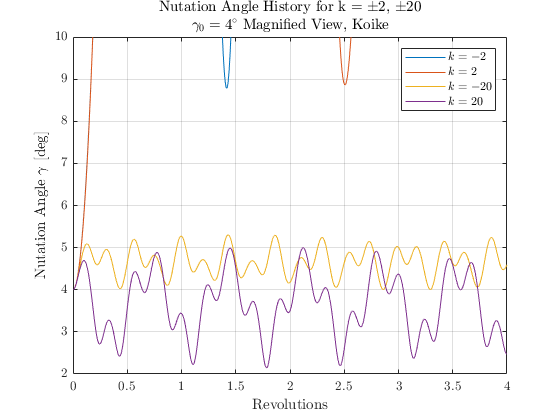

rev = 0:0.001:20; % Integration revolutions

% Iteration for different spin factors
for i = 1:4
    % *Problem (d) part (i)
    % Iteration for different initial gammas
    for j = 1:4
        
        % Nutation History
        [rev, Nut] = Nut_Prec_History(rev,k(i),gamma0(j),I,J);
        
        % Plot Nutation History vs Revolutions
        fig = figure(i);
            grid on; grid minor; box on; hold on;
            if i == 1 || i == 3
                ylim([-3 180]);
            else
                ylim([-3 24]);
            end
            plot(rev, Nut)
    end
    figure(i)
        legend('$\gamma_0 = 0^\circ$', '$\gamma_0 = 8^\circ$', ...
               '$\gamma_0 = 4^\circ$', '$\gamma_0 = 16^\circ$')
        ylabel('Nutation Angle $\gamma$ [deg]')
        xlabel('Revolutions')
        title_str = sprintf('Nutation Angle History when k = %d, Koike',k(i));
        title(title_str)
    
    % Saving Figures
    file_str = sprintf('P1d_Nutation_History_k=%d.png', k(i));
    saveas(fig, fullfile(fdir, file_str));
    
end

close all;

% Symmetry Test
for i = 1:4
    
    % Defining System Properties
    gamma0 = 4;                % Initial perturbation  [deg]
    rev    = 0:0.001:4;        % Integration Revolutions
    k      = [-2 2 -20 20];    % spin factor
    
    % Nutation History
    [rev, Nut] = Nut_Prec_History(rev,k(i),gamma0,I,J);

    % Plotting Nutation History vs Revolutions
    fig = figure(1);
        grid on; grid minor; box on; hold on;
        plot(rev, Nut)
end
    
for i = 1:2
    % Plotting Nutation Angle History vs Revolutions
    figure(1);
        legend('$k = -2$', '$k = 2$', '$k = -20$', '$k = 20$')
        ylabel('Nutation Angle $\gamma$ [deg]')
        xlabel('Revolutions')
        
    if i == 1
        ylim([-3 180]);
        title({'Nutation Angle History for k = $\pm$2, $\pm$20','$\gamma_0 = 4^\circ$, Koike'})
        saveas(fig, fullfile(fdir, 'P1d_symmetry_test.png'));
    else % Magnified View
        ylim([2 10]);
        title({'Nutation Angle History for k = $\pm$2, $\pm$20', '$\gamma_0 = 4^\circ$ Magnified View, Koike'})
        saveas(fig, fullfile(fdir, 'P1d_symmetry_test_close_up.png'));
    end
end